Calculati dezvoltarea MacLaurin a functiei Bessel J0(2x). Determinati R22(x), R43(x) si R24(x) si comparati graficele.

syms x;
f = besselj(0, sym(2)*x);
T=taylor(f, x, 0, 'Order', 11)

$$T = -\frac{x^{10}}{14400}+\frac{x^{8}}{576}-\frac{x^{6}}{36}+\frac{x^{4}}{4}-x^{2}+1$$


R22 = customPade(T, 2, 2, x);
simplifyFraction(R22)

$$ans = -\frac{3\,x^{2}-4}{x^{2}+4}$$

R43 = customPade(T, 4, 3, x);
simplifyFraction(R31)

$$ans = \frac{-x^{3}+6\,x^{2}+24\,x}{6\,\left(3\,x+4\right)}$$

R24 = pade(T, x, 'Order', [sym(2), sym(4)])

$$R24 = -\frac{4\,\left(19\,x^{2}-27\right)}{5\,x^{4}+32\,x^{2}+108}$$

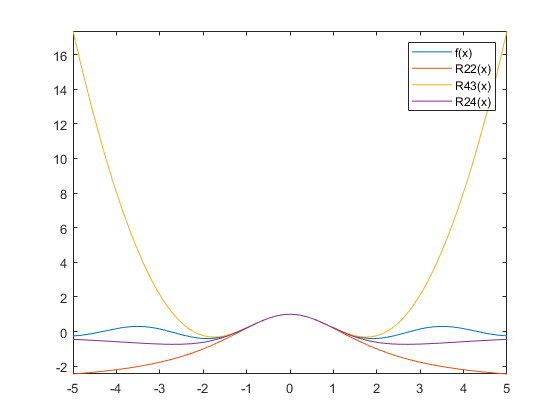

clf
fplot(f, [-5, 5])
hold on
fplot(R22, [-5, 5])
fplot(R43, [-5, 5])
fplot(R24, [-5, 5])
legend('f(x)', 'R22(x)', 'R43(x)', 'R24(x)')